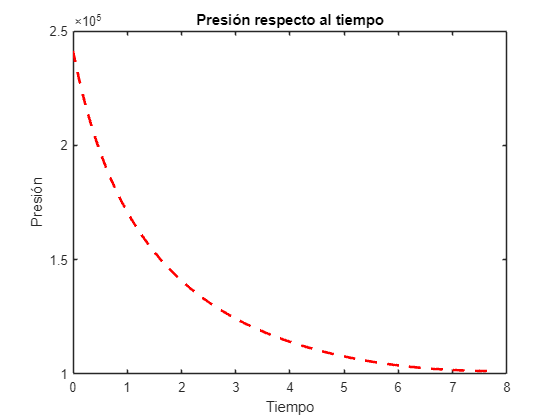

% Limpiar la memoria, la consola y cerrar todas las figuras anteriores
clear; clc; close all;

% Definición de parámetros de tiempo
ti = 0;
tf = 10;  % Ajusta según tu necesidad
dt = 0.01;  % Ajusta según tu necesidad

% Crear vector de tiempo
t = ti:dt:tf;

% Número de pasos de tiempo
nsteps = length(t);

% Vectores para almacenar datos en cada paso de tiempo
p = zeros(1, nsteps);
vy = zeros(1, nsteps);
y = zeros(1, nsteps);
m = zeros(1, nsteps);

% Parámetros del cohete
a = 0.04398;
p0 = 241317;
p(1) = p0;
v0 = 1.5;
vt = 2;
patm = 101325;
da = 1000;
D = 0.0002;
mc = 0.399;
m_water = 0.500;  % Masa inicial de agua en el cohete
g = 9.81;

% Inicializar masa con la masa del cohete más la masa de agua
m(1) = mc + m_water;

%----------------- Graficar Presión respecto al Tiempo --------------------
figure;

% Bucle para calcular la presión en cada paso de tiempo
for i = 1:nsteps
    % Ecuación de Euler para la presión
    p(i+1) = p(i) - (((p(i)^2)*(a)/((p0)*v0))*sqrt(2*(p(i)-patm)/da))*dt;
    
    % Verificar si la presión es menor o igual a la presión atmosférica
    if p(i+1) <= patm
        nsteps = i;
        break;
    end
    
    % Calcular la masa total del cohete (cambia mientras se vacía el agua)
    if m(i) > mc
        m(i+1) = max(mc, m(i) + da*(vt-((p0*v0)/p(i))));
    else
        m(i+1) = mc;  % Cuando la masa llega a mc, se mantiene constante
    end
end

% Graficar la presión
plot(t(1:nsteps), p(1:nsteps), 'r--', 'LineWidth', 2);
xlabel('Tiempo');
ylabel('Presión');
title('Presión respecto al tiempo');

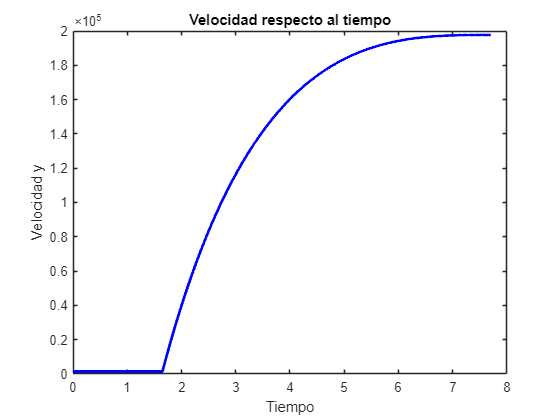


%---------------- Graficar Velocidad respecto al Tiempo -------------------
figure;

% Bucle para calcular la velocidad en cada paso de tiempo
for i = 1:nsteps
    % Ecuación de Euler para la velocidad
    vy(i+1) = vy(i) + ((p(i) - patm) / m(i) - g) * dt;
end

% Graficar la velocidad
plot(t(1:nsteps), vy(1:nsteps), 'b-', 'LineWidth', 2);
xlabel('Tiempo');
ylabel('Velocidad y');
title('Velocidad respecto al tiempo');

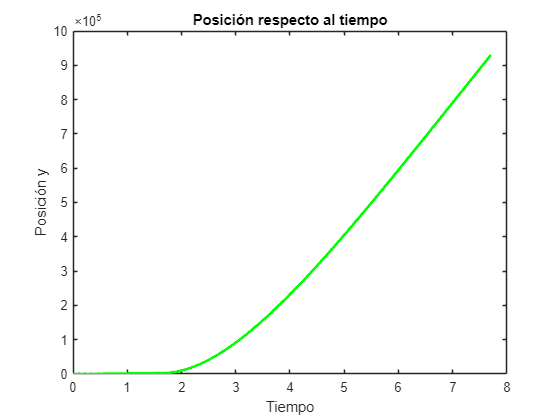


%------------- Graficar Posición respecto al Tiempo -----------------------
figure;

% Bucle para calcular la posición en cada paso de tiempo
for i = 1:nsteps
    % Ecuación de Euler para la posición
    y(i+1) = y(i) + vy(i)*dt + 0.5 * ((p(i) - patm) / m(i) - g) * dt^2;
end

% Graficar la posición
plot(t(1:nsteps), y(1:nsteps), 'g-', 'LineWidth', 2);
xlabel('Tiempo');
ylabel('Posición y');
title('Posición respecto al tiempo');